DSB-SC通信的软件仿真实现

待处理信号

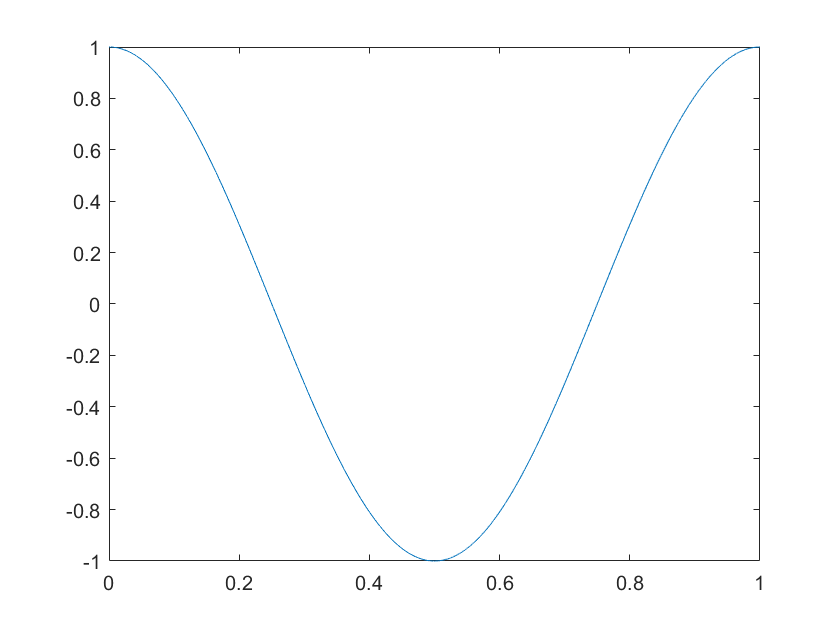

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

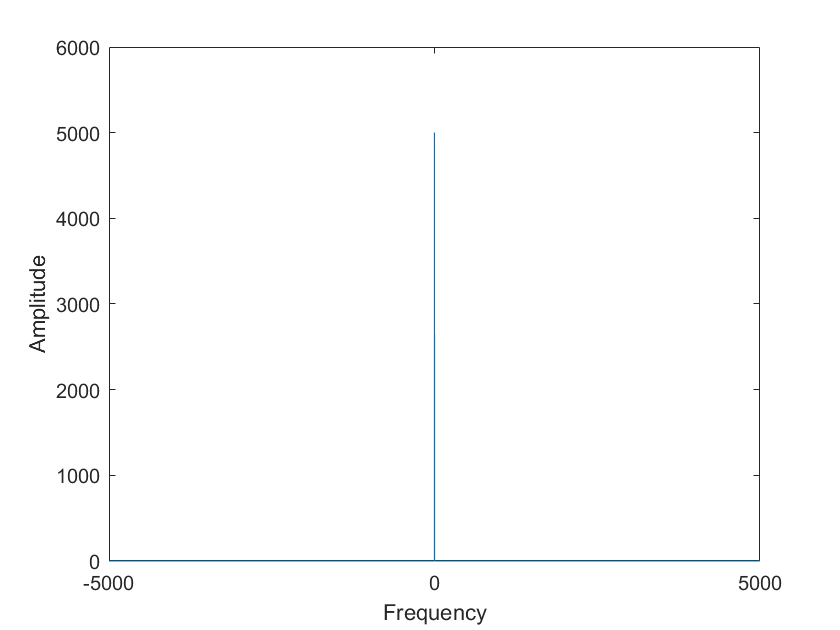

plotF(message, fs);

信号调制

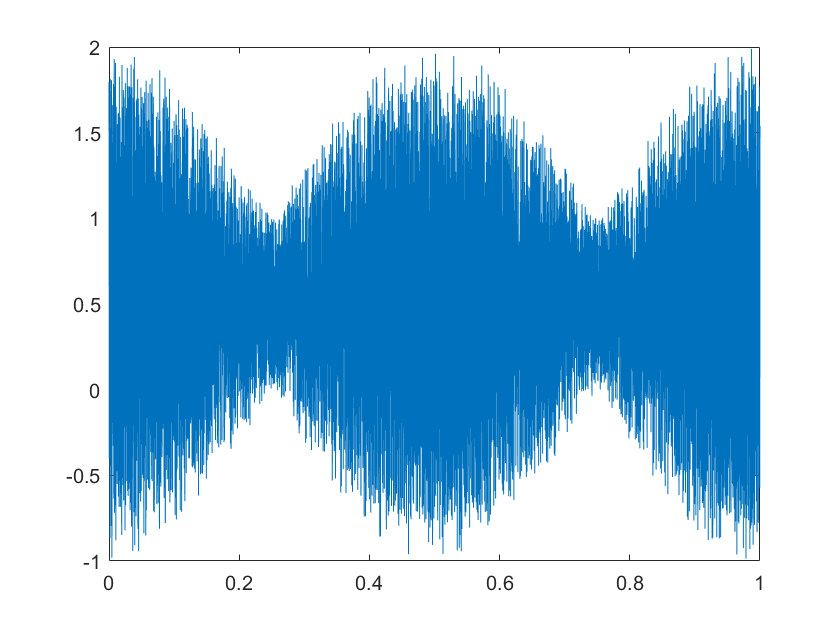

Ac = 1;
carrier = Ac * cos(2*pi*1000*t);
modulated = carrier.* message + rand(1, length(t));
plot(t, modulated);

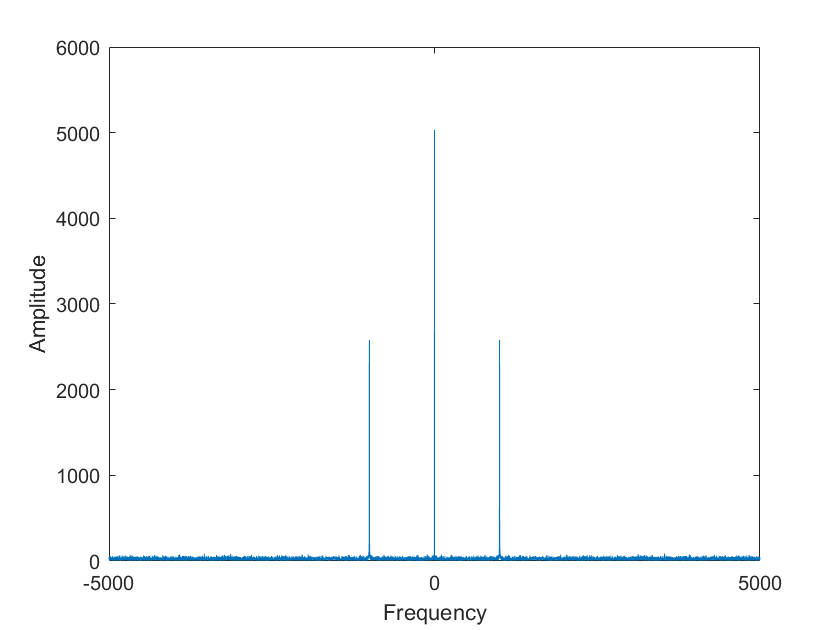

plotF(modulated, fs);

信道

sig_in_channel = modulated;

信号解调

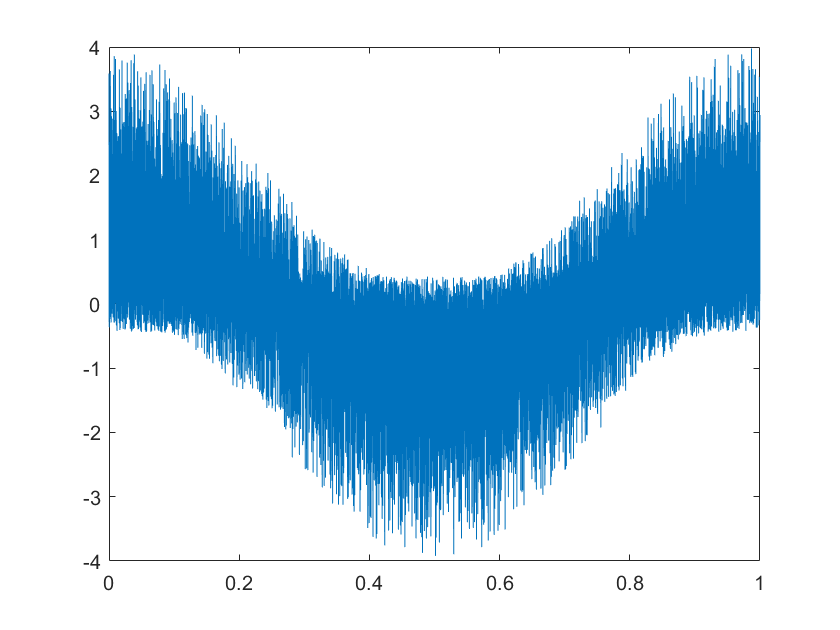

demodulated = 2 * sig_in_channel.* carrier;
plot(t, demodulated);

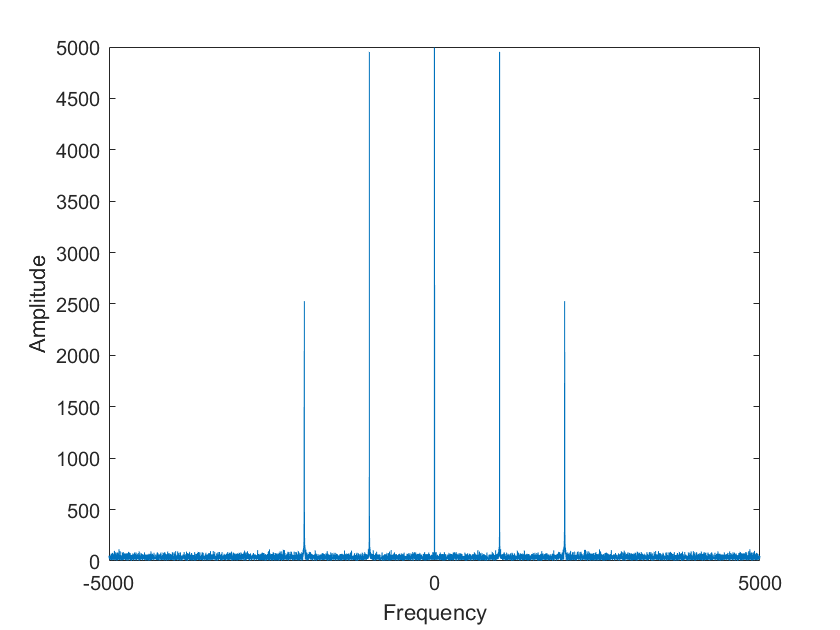

plotF(demodulated, fs);

滤波

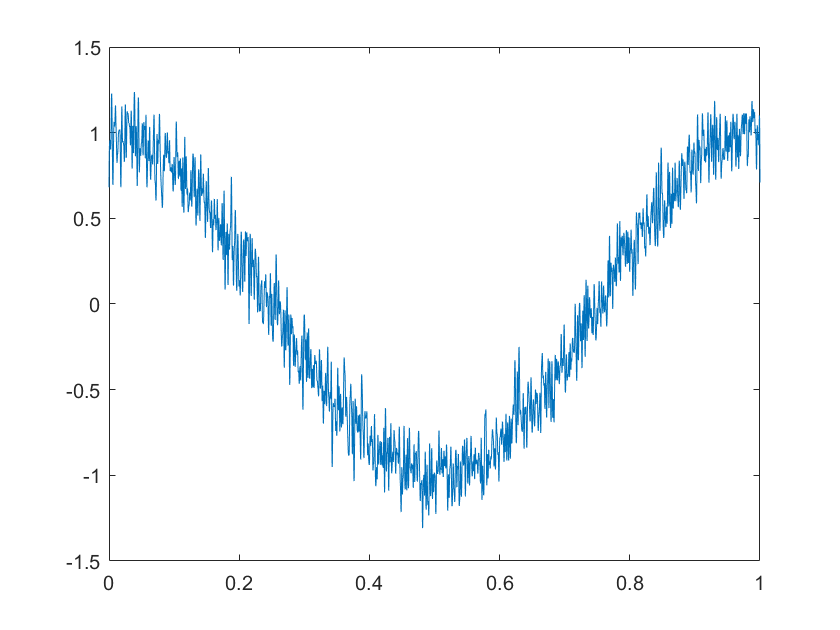

out = lowpass(demodulated, 100, fs);
plot(t, out);

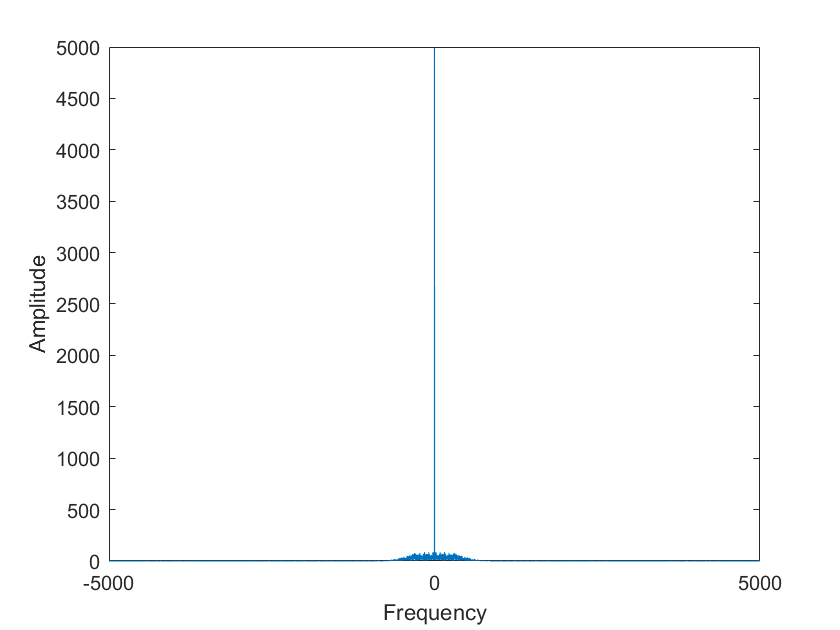

plotF(out, fs);

评估

SNR = bandpower(message, fs, [0, 1]) / 100

SNR = 0.0057